3_d

Hessenberg QR algorithm

epsilon = 1e-10;

A = [3,2;epsilon,1]

A =     3.0000    2.0000
    0.0000    1.0000


B = A(:,:)

B =     3.0000    2.0000
    0.0000    1.0000


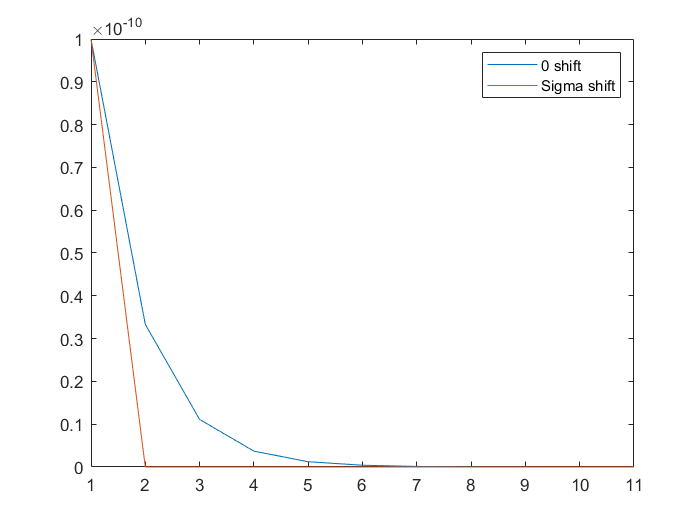


n=10;

sigma=B(2,2);

h21 = [A(2,1)];
h21_shifted = [B(2,1)];

for i=1:n
    [Q,R] = qr(A);
    A = R*Q;
    h21 = [h21 abs(A(2,1))];
    
    [Q,R] = qr(B - sigma*eye(2,2));
    B = R*Q + sigma*eye(2,2);
    h21_shifted = [h21_shifted abs(B(2,1))];
    
    
end

figure(1)
plot(h21)
hold on;
plot(h21_shifted)
legend("0 shift", "Sigma shift")

hold off;

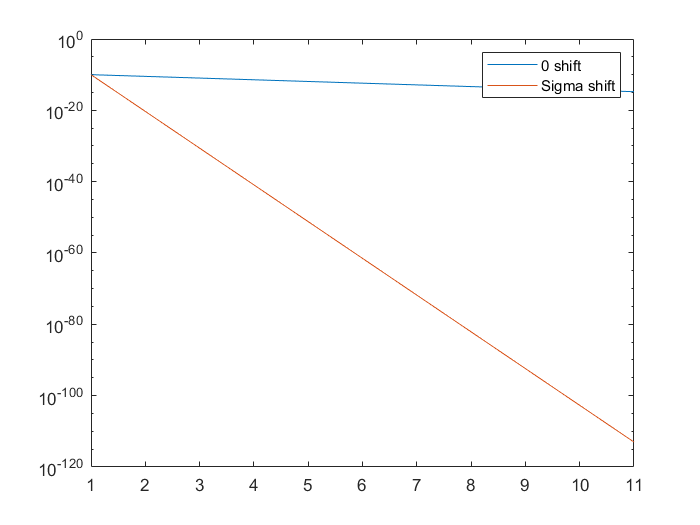

clf

figure(2)
semilogy(h21)
hold on;
semilogy(h21_shifted)
legend("0 shift", "Sigma shift")

Get table

epsilons = [0.4, 0.1, 0.01, 1e-3, 1e-4, 1e-5, 1e-6, 1e-7, 1e-8, 1e-9, 1e-10, 0];

h21_noshift = [];
h21_shifted = [];

n=1;

for j=1:length(epsilons)
    epsilon = epsilons(j);
    
    A = [3,2;epsilon,1];
    B = A(:,:);
    
    sigma=B(2,2);
    
    for i=1:n
        [Q,R] = qr(A);
        A = R*Q;
        
        [Q,R] = qr(B - sigma*eye(2,2));
        B = R*Q + sigma*eye(2,2);
    end
    
    h21_noshift = [h21_noshift abs(A(2,1))];
    h21_shifted = [h21_shifted abs(B(2,1))];
end

h21_noshift;
h21_shifted;
table = [h21_noshift' h21_shifted'];
table_significant = round(table, 3, 'significant');

disp(num2str(table_significant, '%.2e '));

9.61e-02 7.69e-02
3.11e-02 4.99e-03
3.31e-03 5.00e-05
3.33e-04 5.00e-07
3.33e-05 5.00e-09
3.33e-06 5.00e-11
3.33e-07 5.00e-13
3.33e-08 5.00e-15
3.33e-09 5.00e-17
3.33e-10 5.00e-19
3.33e-11 5.00e-21
0.00e+00 0.00e+00


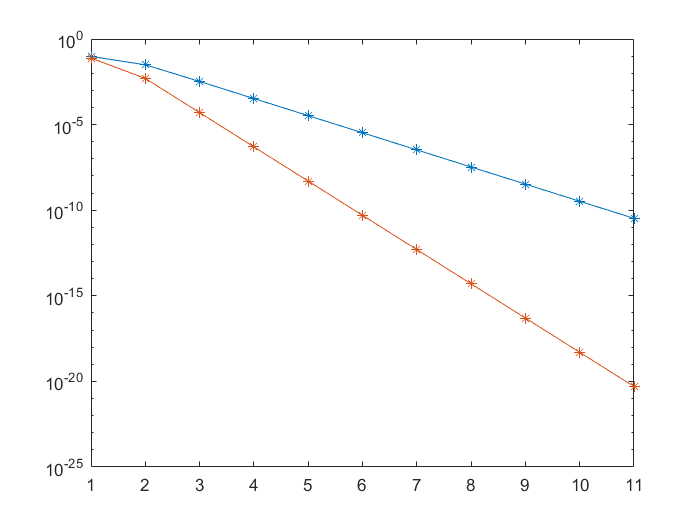


figure(4);
semilogy(table(:,1), "-*");
hold on;
semilogy(table(:,2), "-*");